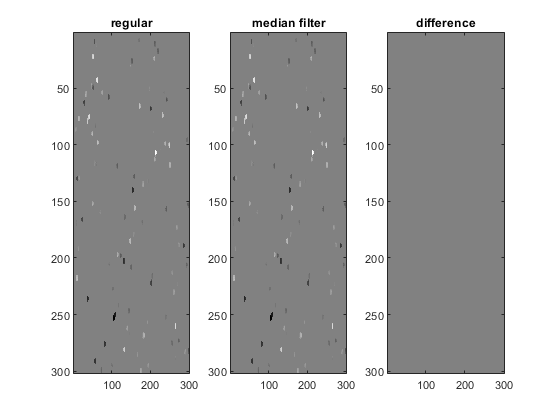

img = im2double(importdata("medfilt_problem_dat.mat"));
img_med1 = medfilt_3x3(img);
img_med2 = medfilt2(img);
img_med_diff = img_med1 - img_med2;
subplot(1,3,1);
imagesc(img_med1)
colormap('gray')
title('regular')
subplot(1,3,2);
imagesc(img_med2)
title('median filter')
colormap('gray')
subplot(1,3,3);
imagesc(img_med_diff)
colormap('gray')
title('difference')

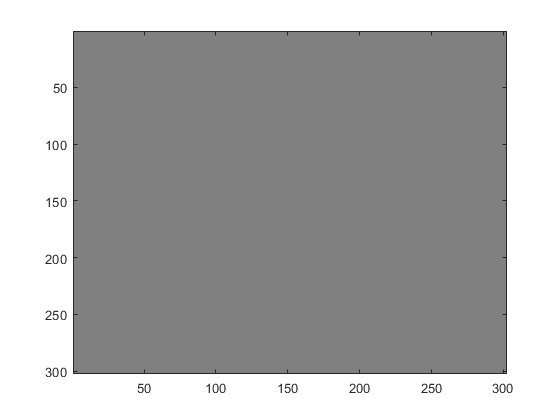

cla();
clf();
imagesc(medfilt2(img, [11,11]))

%2a
img_eye = im2double(imread('img_001.ppm'));
img_eye = img_eye(:,:,2);
img_eye_gaus = gausfilt(img_eye, 1);

g_length = 7

ans = 0.9997

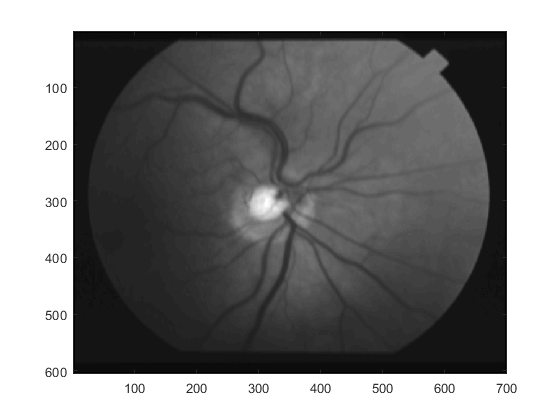

img_eye_mean = mean_filter_no_boarders(img_eye, 3);
imagesc(img_eye_gaus-img_eye_mean)   
colormap('gray');

%2b
img_eye = im2double(imread('img_001.ppm'));
img_eye = img_eye(:,:,2);
img_eye_gaus = gausfilt(img_eye, 1);

g_length = 7

guas_conv_sum = 0.9997


img_eye_gaus2 = gausfilt(img_eye, 1.5);

g_length = 11

guas_conv_sum = 0.9998

img_eye_gaus3 = gausfilt(img_eye, 2);

g_length = 15

guas_conv_sum = 0.9998

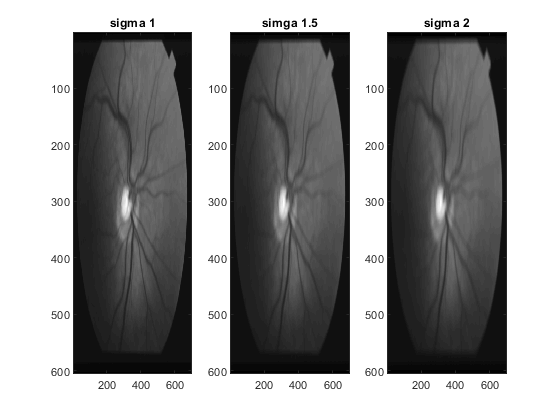

subplot(1,3,1);
imagesc(img_eye_gaus)
colormap('gray')
title('sigma 1')
subplot(1,3,2);
imagesc(img_eye_gaus2)
title('simga 1.5')
colormap('gray')
subplot(1,3,3);
imagesc(img_eye_gaus3)
colormap('gray')
title('sigma 2')

I found that as you increase sigma the filter size also has to grow in order to maintain a sum of 1.

%2c
cla();
clf();




What a normalized guassian filter does is spread smooth value together

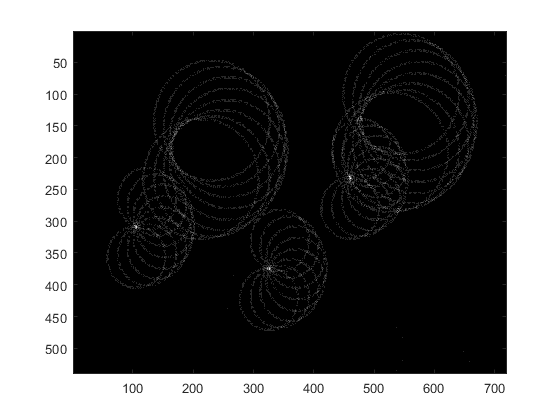

%3
cla();
clf();
img_circle =  im2double(importdata("img_circle.mat"));
accum = zeros(540, 720, 3);

rs_cos = zeros(8,3);
rs_sin = zeros(8,3);
for i=1:8
    rs_cos(i,1) = cos(pi/8 * (i-1)) * 48;
    rs_cos(i,2) = cos(pi/8 * (i-1)) * 50;
    rs_cos(i,3) = cos(pi/8 * (i-1)) * 52;
    rs_sin(i,1) = sin(pi/8 * (i-1)) * 48;
    rs_sin(i,2) = sin(pi/8 * (i-1)) * 50;
    rs_sin(i,3) = sin(pi/8 * (i-1)) * 52;
end
for i=1:540
    for j=1:720
        if img_circle(i,j) > 0
            for k=1:3
                for g=1:8
                    x = round(i + rs_cos(g,k));
                    y = round(j + rs_sin(g,k));
                    if 0 < x && x <= 540 && 0 < y && y <= 720
                        accum(x,y,k) = accum(x,y,k) + 1;
                    end
                end
            end
       end
    end
end
imagesc(accum(:,:,1))

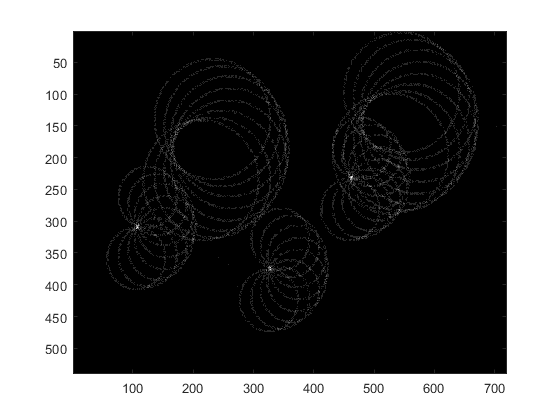

imagesc(accum(:,:,2))

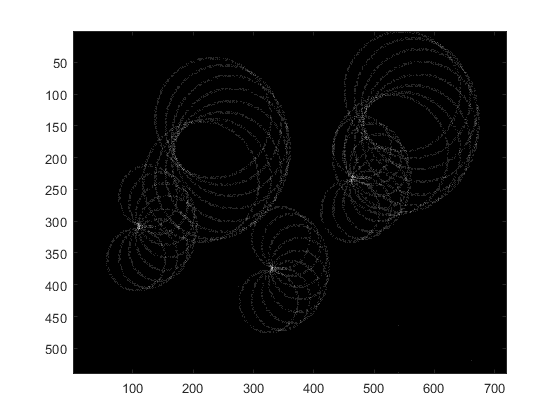

imagesc(accum(:,:,3))

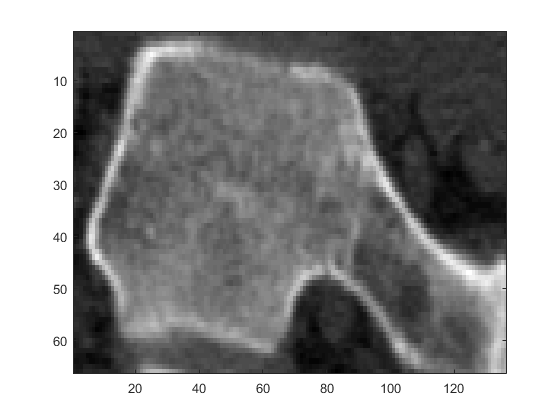

%4
img_y = double(dicomread('series-1/image-000361.dcm'));
img_y_prime = img_y(275:340, 185:320);

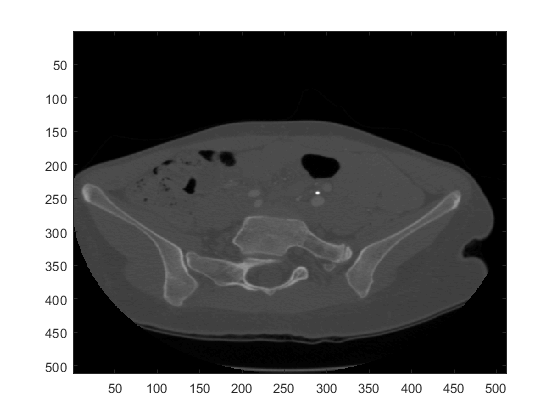

%5


function res2 = medfilt_3x3(img)
    img = padarray(img, [1,1], 0, 'both');
    res = zeros(size(img));
    for i=2:length(img(:,1))-1
        for j=2:length(img(1,:))-1
            res(i,j) = median(img(i-1:i+1, j-1:j+1), 'all');
        end
    end
    res2 = res(2:end-1, 2:end-1);  
end

function value = gaus_value(x,sigma)  
    left = 1 / (((2*pi)^0.5)*sigma);
    exp_value = exp(-1 * ((x^2)/(2*(sigma^2))));
    value = left * exp_value;
end

function count = gaus_length(sigma)
    count = 1;
    value = gaus_value(0, sigma);
    index = 1;
    while value < 0.999
        value = value + 2*gaus_value(index, sigma);
        count = count + 2;
        index = index + 1;
    end
    if rem(count, 2) == 0
        count = count + 1;
    end
end

function res = gausfilt(img, sigma)
    g_length = gaus_length(sigma)
    gaus_conv = zeros(g_length, 1);
    offset = (g_length-1)/2;
    gaus_conv(offset+1) = gaus_value(0, sigma);
    for i=1:offset
        gaus_conv(offset+1-i) = gaus_value(i, sigma);
        gaus_conv(offset+1+i) = gaus_value(i, sigma);
    end
    guas_conv_sum = sum(gaus_conv, 'all')
    res = zeros(size(img));
    for i=offset+1:length(img(:,1))-offset
        for j=offset+1:length(img(1,:))-offset
            temp = img(i-offset:i+offset, j-offset:j+offset);
            temp = temp * gaus_conv;
            temp = temp * gaus_conv.';
            res(i,j) = sum(temp, "all");
        end
    end
    
end

function res = mean_filter_no_boarders(img, filter_size)
    %this code only accpets odd sizes above 3
    offset = (filter_size-1)/2;
    res = zeros(size(img));
    for i=1+offset:length(img(:,1))-offset
        for j=1+offset:length(img(1,:))-offset
            res(i,j) = mean(img(i-offset:i+offset, j-offset:j+offset), 'all');
        end
    end
end
